# Taller 1, puntos 7 a 9: Adaline y compuertas logicas

Misma red de una neurona pero con activacion lineal y regla delta (adaline.m). La correccion es siempre dW = alpha*(d - y)*x con y la salida lineal, y el escalon se usa solo al final para clasificar. Siguiendo el laboratorio 2: entradas en [0,1], salida deseada en [0,1], y el criterio de parada es el error cuadratico EC = 1/2*sum(e^2).

clear; close all; clc
if ~exist('informe/figuras', 'dir'), mkdir('informe/figuras'); end
if ~exist('informe/tablas', 'dir'),  mkdir('informe/tablas');  end

## Parametros del modelo

op.alpha      = 0.05;     % factor relativo de aprendizaje
op.umbral     = 0.5;      % escalon para clasificar la salida lineal
op.salida     = [0 1];
op.error_min  = 1e-3;     % EC objetivo
op.max_epocas = 1000;
op.semilla    = 1;

## Caso sencillo: OR de 2 entradas

[X, d] = compuerta('OR', 2, op.salida);
[w, b, info] = adaline(X, d, op);
fprintf('OR de 2: EC final = %.5f en %d epocas (convergio = %d)\n', info.ec_final, info.epocas, info.convergio);

OR de 2: EC final = 0.13850 en 104 epocas (convergio = 1)


ylin = X * w' + b;
disp(table(X(:,1), X(:,2), d, ylin, predecir(X, w, b, op.umbral, op.salida), ...
     'VariableNames', {'x1', 'x2', 'deseada', 'salida_lineal', 'clasificada'}))

    x1    x2    deseada    salida_lineal    clasificada
    __    __    _______    _____________    ___________

    0     0        0           0.2574            0     
    0     1        1          0.74947            1     
    1     0        1          0.73499            1     
    1     1        1           1.2271            1     



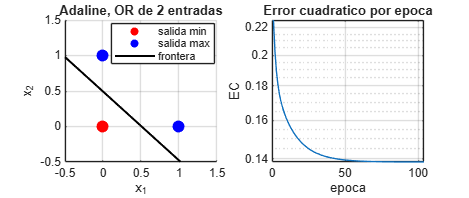


figure('Position', [100 100 900 380]);
subplot(1,2,1); graficar_frontera(X, d, w, b, op.umbral, 'Adaline, OR de 2 entradas');
subplot(1,2,2); semilogy(info.ec_por_epoca); grid on
xlabel('epoca'); ylabel('EC'); title('Error cuadratico por epoca');
guardar_fig('ada_or2');

## Reporte 1: todas las compuertas, incluida la XOR

Se reporta el EC al que llego, las epocas y cuantos patrones clasifica bien despues del escalon. La XOR va para mostrar que una sola neurona no la puede aprender aunque el EC baje algo.

casos = {'AND', 2; 'AND', 3; 'AND', 4; 'OR', 2; 'OR', 3; 'OR', 4; 'XOR', 2};
filas = {};
for c = 1:size(casos, 1)
    [X, d] = compuerta(casos{c,1}, casos{c,2}, op.salida);
    [w, b, info] = adaline(X, d, op);
    acc = 100 * mean(predecir(X, w, b, op.umbral, op.salida) == d);
    filas(end+1, :) = {casos{c,1}, casos{c,2}, info.epocas, info.ec_final, info.convergio, acc}; %#ok<SAGROW>
end
R1 = cell2table(filas, 'VariableNames', {'Compuerta', 'Entradas', 'Epocas', 'EC_final', 'Convergio', 'Exactitud'});
disp(R1)

    Compuerta    Entradas    Epocas    EC_final    Convergio    Exactitud
    _________    ________    ______    ________    _________    _________

     {'AND'}        2          67      0.13846       true           100  
     {'AND'}        3         115       0.2953       true           100  
     {'AND'}        4          59      0.42917       true         93.75  
     {'OR' }        2         104       0.1385       true           100  
     {'OR' }        3          53      0.27266       true          87.5  
     {'OR' }        4          86       0.3697       true         93.75  
     {'XOR'}        2         128      0.55396       true            25  



writetable(R1, 'informe/tablas/ada_compuertas.csv');

## Reporte 2: efecto de alpha

Con alpha muy chico se demora, con alpha muy grande el error se dispara en vez de bajar. Se prueba en AND y OR de 2 y 4 entradas.

alphas = [0.001 0.01 0.05 0.1 0.2 0.5 1];
filas = {};
for c = 1:size(casos, 1) - 1
    [X, d] = compuerta(casos{c,1}, casos{c,2}, op.salida);
    for a = alphas
        o = op; o.alpha = a;
        [w, b, info] = adaline(X, d, o);
        acc = 100 * mean(predecir(X, w, b, o.umbral, o.salida) == d);
        filas(end+1, :) = {casos{c,1}, casos{c,2}, a, info.epocas, info.ec_final, acc}; %#ok<SAGROW>
    end
end
R2 = cell2table(filas, 'VariableNames', {'Compuerta', 'Entradas', 'Alpha', 'Epocas', 'EC_final', 'Exactitud'});
disp(R2)

    Compuerta    Entradas    Alpha    Epocas     EC_final     Exactitud
    _________    ________    _____    ______    __________    _________

     {'AND'}        2        0.001     1000        0.12903        100  
     {'AND'}        2         0.01      327        0.12759        100  
     {'AND'}        2         0.05       67        0.13846        100  
     {'AND'}        2          0.1       27        0.15407        100  
     {'AND'}        2          0.2       47        0.19531        100  
     {'AND'}        2          0.5       20            0.5         75  
     {'AND'}        2            1     1000     4.9943e+05         50  
     {'AND'}        3        0.001     1000        0.25899       87.5  
     {'AND'}        3         0.01      282        0.25831        100  
     {'AND'}        3         0.05      115         0.2953        100  
     {'AND'}        3          0.1       71        0.35155        100  
     {'AND'}        3          0.2       43        0.50684     

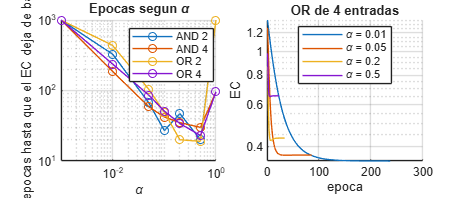

writetable(R2, 'informe/tablas/ada_alpha.csv');

figure('Position', [100 100 900 380]);
subplot(1,2,1); hold on
for c = [1 3 4 6]
    m = strcmp(R2.Compuerta, casos{c,1}) & R2.Entradas == casos{c,2};
    plot(R2.Alpha(m), R2.Epocas(m), '-o', 'DisplayName', sprintf('%s %d', casos{c,1}, casos{c,2}));
end
set(gca, 'XScale', 'log', 'YScale', 'log'); grid on
xlabel('\alpha'); ylabel('epocas hasta que el EC deja de bajar'); legend('Location', 'best');
title('Epocas segun \alpha');

subplot(1,2,2); hold on
[X, d] = compuerta('OR', 4, op.salida);
for a = [0.01 0.05 0.2 0.5]
    o = op; o.alpha = a;
    [~, ~, info] = adaline(X, d, o);
    semilogy(info.ec_por_epoca, 'DisplayName', sprintf('\\alpha = %g', a));
end
set(gca, 'YScale', 'log'); grid on; xlim([0 300]);
xlabel('epoca'); ylabel('EC'); title('OR de 4 entradas'); legend('Location', 'best');
guardar_fig('ada_alpha');

## Reporte 3: efecto del criterio de parada y del umbral de clasificacion

Con una tabla de verdad el EC nunca llega a 1e-3, porque una recta no puede pasar exacto por los 0 y 1 deseados. Por eso el criterio que de verdad para el entrenamiento es tol_cambio: cuando el EC deja de bajar entre una epoca y la siguiente. Se prueba junto con el umbral del escalon.

filas = {};
[X, d] = compuerta('AND', 2, op.salida);
for tol = [1e-2 1e-3 1e-4 1e-5 1e-6]
    for u = [0.3 0.5 0.7]
        o = op; o.tol_cambio = tol; o.umbral = u;
        [w, b, info] = adaline(X, d, o);
        acc = 100 * mean(predecir(X, w, b, o.umbral, o.salida) == d);
        filas(end+1, :) = {tol, u, info.epocas, info.ec_final, acc}; %#ok<SAGROW>
    end
end
R3 = cell2table(filas, 'VariableNames', {'Tol_cambio', 'Umbral', 'Epocas', 'EC_final', 'Exactitud'});
disp(R3)

    Tol_cambio    Umbral    Epocas    EC_final    Exactitud
    __________    ______    ______    ________    _________

        0.01       0.3         6      0.16221         75   
        0.01       0.5         6      0.16221        100   
        0.01       0.7         6      0.16221        100   
       0.001       0.3        13       0.1464         75   
       0.001       0.5        13       0.1464        100   
       0.001       0.7        13       0.1464        100   
      0.0001       0.3        34      0.13921        100   
      0.0001       0.5        34      0.13921        100   
      0.0001       0.7        34      0.13921        100   
       1e-05       0.3        54       0.1385        100   
       1e-05       0.5        54       0.1385        100   
       1e-05       0.7        54       0.1385        100   
       1e-06       0.3        67      0.13846        100   
       1e-06       0.5        67      0.13846        100   
       1e-06       0.7        67      0

writetable(R3, 'informe/tablas/ada_tol_umbral.csv');

## Perceptron contra Adaline en las mismas compuertas

Los dos con alpha = 0.05 y la misma semilla. El perceptron para apenas clasifica bien; el Adaline sigue hasta que la salida lineal se acerca a la deseada, por eso gasta mas epocas.

filas = {};
for c = 1:size(casos, 1)
    [X, d] = compuerta(casos{c,1}, casos{c,2}, [0 1]);
    op_p = struct('regla', 3, 'alpha', 0.05, 'umbral', 0.5, 'salida', [0 1], 'max_epocas', 1000, 'semilla', 1);
    [wp, bp, ip] = perceptron(X, d, op_p);
    op_a = op; op_a.alpha = 0.05;
    [wa, ba, ia] = adaline(X, d, op_a);
    filas(end+1, :) = {casos{c,1}, casos{c,2}, ip.epocas, 100*mean(predecir(X, wp, bp, 0.5, [0 1]) == d), ...
                       ia.epocas, 100*mean(predecir(X, wa, ba, 0.5, [0 1]) == d)}; %#ok<SAGROW>
end
R4 = cell2table(filas, 'VariableNames', {'Compuerta', 'Entradas', 'Epocas_perc', 'Exact_perc', 'Epocas_ada', 'Exact_ada'});
disp(R4)

    Compuerta    Entradas    Epocas_perc    Exact_perc    Epocas_ada    Exact_ada
    _________    ________    ___________    __________    __________    _________

     {'AND'}        2              4           100            67            100  
     {'AND'}        3              7           100           115            100  
     {'AND'}        4              6           100            59          93.75  
     {'OR' }        2              2           100           104            100  
     {'OR' }        3              3           100            53           87.5  
     {'OR' }        4              5           100            86          93.75  
     {'XOR'}        2           1000            50           128             25  



writetable(R4, 'informe/tablas/perc_vs_ada_compuertas.csv');